### 09/04/2025 0mT  2.65-2.658 GHz -42dBm

%% Setup
clc 
close all
clear all

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load('\\badwwmi-k04-qtm\data_qtm\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-10dBm_7mK_2.6GHz_2ndMeas_09-Apr-2025_@_10-35-08\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-10dBm_7mK_2.6GHz_2ndMeas_@10-35-08.mat', ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 100);

% %% Comparison Plot
% cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit
tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 6, 400, 6, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T1 = [fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)];


### 17/04/2025 0.5 mT  2.6495-2.6575 GHz -42 dBm 

%% Setup
clc 
close all
clear all

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load('\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\Low_Field_Batch\mw_time_spectrum_r19s2_nat_Er_CWO_2653.5_MHz_-10dBm_7mK_HT_LowFieldDecay_17-Apr-2025_@_15-16-22\mw_time_spectrum_r19s2_nat_Er_CWO_2653.5_MHz_-10dBm_7mK_HT_LowFieldDecay_@15-16-22.mat', ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot
% cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);
%% Plot Decay & Exponential Fit
tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 6, 400, 6, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})


### 17/04/2025 1 mT  2.6485-2.6565 GHz -42 dBm 

%% Setup
clc 
close all
clear all

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load('\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\Low_Field_Batch\mw_time_spectrum_r19s2_nat_Er_CWO_2652.5_MHz_-10dBm_7mK_HT_LowFieldDecay_17-Apr-2025_@_18-19-28\mw_time_spectrum_r19s2_nat_Er_CWO_2652.5_MHz_-10dBm_7mK_HT_LowFieldDecay_@18-19-28.mat', ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot
% cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);
fr_max = freq(fr_idx);

minus_alpha_L = -alpha_L;


% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 6, 400, 6, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})



### 17/04/2025 1.5 mT  2.6485-2.6565 GHz -42 dBm 

%% Setup
clc 
close all
clearvars -except T1

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load('\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_2649.8_MHz_-10dBm_7mK_HT_LowFieldDecay_17-Apr-2025_@_21-21-55\mw_time_spectrum_r19s2_nat_Er_CWO_2649.8_MHz_-10dBm_7mK_HT_LowFieldDecay_@21-21-55.mat', ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot
% cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[5, 4000, 5, 400, 6, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})


### 19/04/2025 6 mT  2.6485-2.6565 GHz -42 dBm 

% %% Setup
% clc 
% close all
% clear all
% 
% vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
%     "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
% load('\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\5-8mT Batch\mw_time_spectrum_r19s2_nat_Er_CWO_2535_MHz_-10dBm_7mK_HT_MidFieldDecay_19-Apr-2025_@_08-11-15\mw_time_spectrum_r19s2_nat_Er_CWO_2535_MHz_-10dBm_7mK_HT_MidFieldDecay_@08-11-15.mat', ...
%     vari{:});
% 
% freq = yy/1e9;
% fr_left = 1;
% fr_right = length(freq);
% 
% freq = freq(fr_left:fr_right);
% zz = zz(fr_left:fr_right,:);
% zzph = zzph(fr_left:fr_right, :);
% 
% table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
%     'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})
% 

% %% Correction Procedure
% [zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% % %% Comparison Plot
% % cc = turbo(size(zz,2));
% % plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

% %% Intensity Plot
% [transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);

% %% Plot Decay & Exponential Fit
% 
% tr_1 = alpha_L(:, 1);
% [max_tr1, fr_idx] = max(tr_1);
% 
% minus_alpha_L = -alpha_L;
% 
% fr_max = freq(fr_idx);
% 
% % Tri-exponential fit
% 
% fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
%     dependent="y",independent="x",...
%     coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
% [f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 5000, 6, 500, 6, 100, -2], 'Robust', 'LAR');
% 
% fit_coeff = coeffvalues(f);
% var_names = string(coeffnames(f))'
% 
% figure;
% subplot(1,2,1)
% plot(xx, minus_alpha_L(fr_idx, :), 'm.')
% grid on; grid minor
% title(strcat("Decay @", num2str(fr_max), "GHz"))
% hold on
% plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)
% 
% subplot(1,2,2)
% plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
% grid on; grid minor
% title(strcat("Decay @", num2str(fr_max), "GHz"))
% hold on
% plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)
% 
% T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
%     'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})
% 

### 30/04/2025 5 mT  2.6485-2.6565 GHz -42 dBm 

%% Setup
clc 
close all
clear all

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\5mTbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2549_MHz_-5dBm_7mK_FieldBatch_30-Apr-2025_@_13-28-57\mw_time_spectrum_r19s2_nat_Er_CWO_2549_MHz_-5dBm_7mK_FieldBatch_@13-28-57.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

%smoothing
zz = smoothdata(zz, "movmean", 2);

% Pumping & Decay

cc = turbo(size(pumping_zz, 2));
figure;
subplot(1,2,1)
for i = 1:size(pumping_zz,2)
    plot(freq, pumping_zz(:,i), 'Color',cc(i,:))
    hold on
    grid on
    grid minor
end
title("Pumping")
xlabel("Frequency (GHz)")
ylabel("S_{21} (dBm)")

subplot(1,2,2)

cc2 = turbo(size(zz, 2));
for i = 1:size(zz,2)
    plot(freq, zz(:,i), 'Color',cc2(i,:))
    hold on
    grid on
    grid minor
end
title("Decay")
xlabel("Frequency (GHz)")
ylabel("S_{21} (dBm)")


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot

% cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[5, 4000, 5, 400, 6, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

### 30/04/2025 6.5 mT  2.512-2.522 GHz -42 dBm 

%% Setup
clc 
close all
clear all

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\5mTbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2517_MHz_-5dBm_7mK_FieldBatch_30-Apr-2025_@_15-42-07\mw_time_spectrum_r19s2_nat_Er_CWO_2517_MHz_-5dBm_7mK_FieldBatch_@15-42-07.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

zz_smooth = smoothdata(zz, "movmean", 2);

figure;
plot(freq, zz(:,2000))
hold on
plot(freq, zz_smooth(:,2500))

zz = zz_smooth;
clear zz_smooth

% Pumping & Decay

cc = turbo(size(pumping_zz, 2));
figure;
subplot(1,2,1)
for i = 1:size(pumping_zz,2)
    plot(freq, pumping_zz(:,i), 'Color',cc(i,:))
    hold on
    grid on
    grid minor
end
title("Pumping")
xlabel("Frequency (GHz)")
ylabel("S_{21} (dBm)")

subplot(1,2,2)

cc2 = turbo(size(zz, 2));
for i = 1:size(zz,2)
    plot(freq, zz(:,i), 'Color',cc2(i,:))
    hold on
    grid on
    grid minor
end
title("Decay")
xlabel("Frequency (GHz)")
ylabel("S_{21} (dBm)")


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot

% cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
% [transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);
[transmat, alpha_L] = intensity_analysis_visualization(freq, db2mag(zz),[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[5, 4000, 5, 400, 6, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})


### 30/04/2025 7 mT  2.6485-2.6565 GHz -42 dBm 

%% Setup
clc 
close all
clear all

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\5mTbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2501_MHz_-5dBm_7mK_FieldBatch_30-Apr-2025_@_17-54-42\mw_time_spectrum_r19s2_nat_Er_CWO_2501_MHz_-5dBm_7mK_FieldBatch_@17-54-42.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

zz_smooth = smoothdata(zz, "movmean", 6);

figure;
plot(freq, zz(:,2000))
hold on
plot(freq, zz_smooth(:,2500))

% Pumping & Decay

cc = turbo(size(pumping_zz, 2));
figure;
subplot(1,2,1)
for i = 1:size(pumping_zz,2)
    plot(freq, pumping_zz(:,i), 'Color',cc(i,:))
    hold on
    grid on
    grid minor
end
title("Pumping")
xlabel("Frequency (GHz)")
ylabel("S_{21} (dBm)")

subplot(1,2,2)

cc2 = turbo(size(zz, 2));
for i = 1:size(zz,2)
    plot(freq, zz_smooth(:,i), 'Color',cc2(i,:))
    hold on
    grid on
    grid minor
end
title("Decay")
xlabel("Frequency (GHz)")
ylabel("S_{21} (dBm)")


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot

cc = turbo(size(zz,2));
plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_smooth,[0.9 1.01], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[5, 4000, 5, 400, 6, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})



### 30/04/2025 Zero Field  2.6485-2.6565 GHz -42 dBm 

%% Setup
clc 
close all
clear all

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-5dBm_7mK_26_4th_Decay_Meas_test_30-Apr-2025_@_21-02-19\mw_time_spectrum_r19s2_nat_Er_CWO_2654_MHz_-5dBm_7mK_26_4th_Decay_Meas_test_@21-02-19.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

% Smoothing
zz = smoothdata(zz, 'movmean', 2);
% Pumping & Decay
plot_pumping_decay(freq, zz, pumping_zz);


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot

cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[5, 4000, 5, 400, 6, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T1 = [fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)];

## New Low Field Batch 01/05-02/05/2025

8 Measurements ranging from 0.5 to 2.5 mT

### 01/05/2025 2.65406 - 0.5 mT -42 dBm 

%% Setup
clc 
close all
clearvars -except T1

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\lowfieldbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2654.06_MHz_-5dBm_7mK_FieldBatch_01-May-2025_@_10-51-16\mw_time_spectrum_r19s2_nat_Er_CWO_2654.06_MHz_-5dBm_7mK_FieldBatch_@10-51-16.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

ans = 1×4 table
      Power       Center Frequency           Range              Duration  
    __________    ________________    ____________________    ____________

    {'-42dBm'}     {'2.6541GHz'}      {'2.6511-2.6571GHz'}    {[03:13:30]}


% Smoothing
zz = smoothdata(zz, 'movmean', 2);
% Pumping & Decay
% plot_pumping_decay(freq, zz, pumping_zz);

%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot
cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

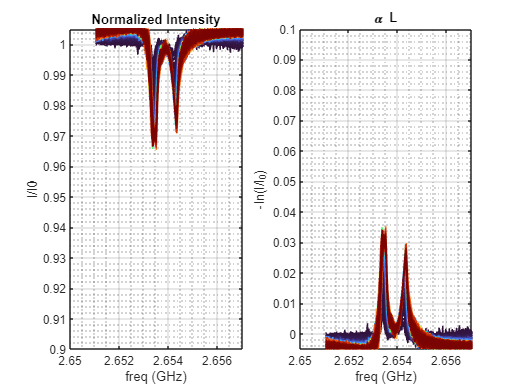

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[5, 4000, 5, 400, 6, 40, -2], 'Robust', 'LAR');

Success, but fitting stopped because change in residuals less than tolerance (TolFun).



fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

var_names = 1×7 string array
    "a"    "tau1"    "b"    "tau2"    "c"    "tau3"    "offset"


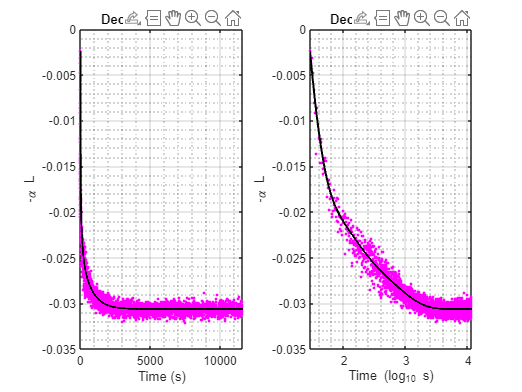


figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)


T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T = 1×6 table
        a           b           c        tau1      tau2      tau3 
    _________    ________    _______    ______    ______    ______

    0.0069098    0.008597    0.11156    708.91    107.55    14.186



disp(gof)

           sse: 5.5821e-05
       rsquare: 0.9977
           dfe: 3408
    adjrsquare: 0.9977
          rmse: 1.2798e-04




T1 = [T1; fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)];

### 01/05/2025 2.65362 - 0.75 mT -42 dBm 

%% Setup
clc 
close all
clearvars -except T1

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\lowfieldbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2653.62_MHz_-5dBm_7mK_FieldBatch_01-May-2025_@_14-07-49\mw_time_spectrum_r19s2_nat_Er_CWO_2653.62_MHz_-5dBm_7mK_FieldBatch_@14-07-49.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})



% Smoothing

zz = smoothdata(zz, 'movmean', 2);

% Pumping & Decay

cc = turbo(size(pumping_zz, 2));
figure;
subplot(1,2,1)
for i = 1:size(pumping_zz,2)
    plot(freq, pumping_zz(:,i), 'Color',cc(i,:))
    hold on
    grid on
    grid minor
end
title("Pumping")
xlabel("Frequency (GHz)")
ylabel("S_{21} (dBm)")

subplot(1,2,2)

cc2 = turbo(size(zz, 2));
for i = 1:size(zz,2)
    plot(freq, zz(:,i), 'Color',cc2(i,:))
    hold on
    grid on
    grid minor
end
title("Decay")
xlabel("Frequency (GHz)")
ylabel("S_{21} (dBm)")


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot

cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);


%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 10, 400, 10, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})
T1 = [T1; fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)]

### 01/05/2025 2.65256GHz - 1 mT -42 dBm 

%% Setup
clc 
close all
clearvars -except T1


vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\lowfieldbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2652.6_MHz_-5dBm_7mK_FieldBatch_01-May-2025_@_17-23-49\mw_time_spectrum_r19s2_nat_Er_CWO_2652.6_MHz_-5dBm_7mK_FieldBatch_@17-23-49.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

% Smoothing
zz = smoothdata(zz, 'movmean', 3);
% Pumping & Decay
plot_pumping_decay(freq, zz, pumping_zz)


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot

cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);


%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 10, 400, 10, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T1 = [T1; fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)]

### 01/05/2025 2.65256GHz - 1.25 mT -42 dBm 

%% Setup
clc 
close all
clearvars -except T1

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\lowfieldbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2651.3_MHz_-5dBm_7mK_FieldBatch_01-May-2025_@_20-39-43\mw_time_spectrum_r19s2_nat_Er_CWO_2651.3_MHz_-5dBm_7mK_FieldBatch_@20-39-43.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

% Smoothing
zz = smoothdata(zz, 'movmean', 4);
% Pumping & Decay
plot_pumping_decay(freq, zz, pumping_zz)


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot

cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);


%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 10, 400, 10, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T1 = [T1; fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)]

### 02/05/2025 2.64957 GHz- 1.5 mT -42 dBm 

%% Setup
clc 
close all
clearvars -except T1

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\lowfieldbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2649.5_MHz_-5dBm_7mK_FieldBatch_01-May-2025_@_23-55-42\mw_time_spectrum_r19s2_nat_Er_CWO_2649.5_MHz_-5dBm_7mK_FieldBatch_@23-55-42.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

% Smoothing
zz = smoothdata(zz, 'movmean', 4);
% Pumping & Decay
plot_pumping_decay(freq, zz, pumping_zz)


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

% %% Comparison Plot

cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

%% Intensity Plot
[transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);


%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 10, 400, 10, 40, -2], 'Robust', 'LAR');

fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)

T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T1 = [T1; fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)]

### 02/05/2025 2.6454 GHz - 2 mT -42 dBm 

%% Setup
clc 
clearvars -except T1

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\lowfieldbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2645.4_MHz_-5dBm_7mK_FieldBatch_02-May-2025_@_03-11-52\mw_time_spectrum_r19s2_nat_Er_CWO_2645.4_MHz_-5dBm_7mK_FieldBatch_@03-11-52.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

ans = 1×4 table
      Power       Center Frequency           Range              Duration  
    __________    ________________    ____________________    ____________

    {'-42dBm'}     {'2.6454GHz'}      {'2.6424-2.6484GHz'}    {[03:13:31]}


% Smoothing
zz = smoothdata(zz, 'movmean', 4);
zzph = smoothdata(zzph, 'movmean', 4);
% Pumping & Decay
% plot_pumping_decay(freq, zz, pumping_zz)


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 50);

zzph_corrected = smoothdata(zzph_corrected, 'movmean', 2);
zz_corrected = smoothdata(zz_corrected, 'movmean', 2);

% %% Comparison Plot

cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

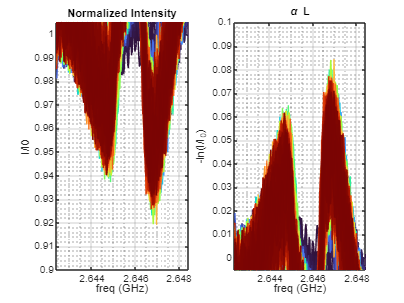

%% Intensity Plot
% [transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);
[transmat, alpha_L] = intensity_analysis_visualization(freq, db2mag(zz),[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx', minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 10, 400, 10, 40, -2], 'Robust', 'LAR');

Fitting stopped because the number of iterations or function evaluations exceeded the specified maximum.



fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

var_names = 1×7 string array
    "a"    "tau1"    "b"    "tau2"    "c"    "tau3"    "offset"


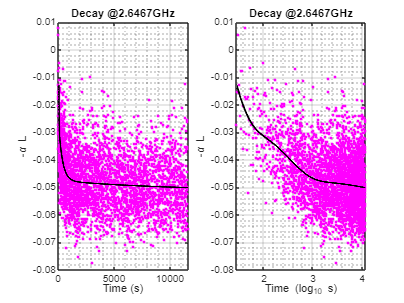


figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)


T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T = 1×6 table
        a           b           c        tau1     tau2      tau3 
    _________    ________    ________    ____    ______    ______

    0.0037488    0.021401    0.081768    9972    343.75    16.834



T1 = [T1; fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)]

### 02/05/2025 2.6413 GHz - 2.25 mT -42 dBm 

%% Setup
clc 
close all
clearvars -except T1

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\lowfieldbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2641.3_MHz_-5dBm_7mK_FieldBatch_02-May-2025_@_06-27-50\mw_time_spectrum_r19s2_nat_Er_CWO_2641.3_MHz_-5dBm_7mK_FieldBatch_@06-27-50.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

ans = 1×4 table
      Power       Center Frequency           Range              Duration  
    __________    ________________    ____________________    ____________

    {'-42dBm'}     {'2.6413GHz'}      {'2.6383-2.6443GHz'}    {[03:13:36]}


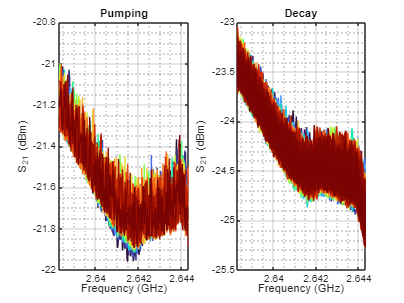

% Smoothing
zz = smoothdata(zz,'movmean', 3);
zzph = smoothdata(zzph, 'movmean', 4);

% Pumping & Decay
plot_pumping_decay(freq, zz, pumping_zz)


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 10);

zzph_corrected = smoothdata(zzph_corrected, 'movmean', 2);
zz_corrected = smoothdata(zz_corrected, 'movmean', 2);

% %% Comparison Plot

cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

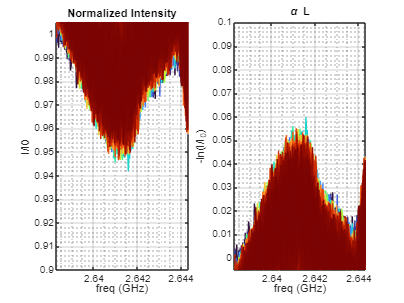

%% Intensity Plot
% [transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);
[transmat, alpha_L] = intensity_analysis_visualization(freq, db2mag(zz),[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx',minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 10, 400, 10, 40, -2], 'Robust', 'LAR');

Success, but fitting stopped because change in residuals less than tolerance (TolFun).



fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

var_names = 1×7 string array
    "a"    "tau1"    "b"    "tau2"    "c"    "tau3"    "offset"


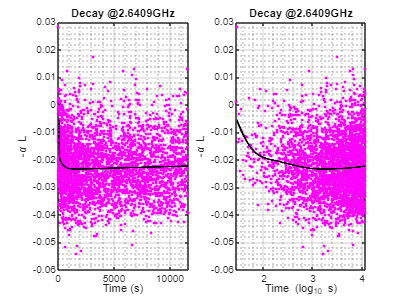


figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)


T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T = 1×6 table
        a            b           c       tau1      tau2      tau3 
    _________    _________    _______    _____    ______    ______

    -0.010746    0.0054614    0.05464    87156    337.72    19.958



T1 = [T1; fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)]

### 02/05/2025 2.6413 GHz - 2.5 mT -42 dBm 

%% Setup
clc 
close all
clearvars -except T1

vari = {"bg_RF", "bg_PH", "xx", "yy", "zz", "zzed", "zzlin", "zzph",...
    "pumping_zz", "pumping_zzph", "vna_f0", "vna_f1", "vna_fc", "vna_pow", "n_zz", "n_zzph"};
load("\\badwwmi-k04-qtm\Data_QTM\_data\run19\Er_CWO\lowfieldbatch_time_spectrum\mw_time_spectrum_r19s2_nat_Er_CWO_2636.5_MHz_-5dBm_7mK_FieldBatch_02-May-2025_@_09-43-55\mw_time_spectrum_r19s2_nat_Er_CWO_2636.5_MHz_-5dBm_7mK_FieldBatch_@09-43-55.mat", ...
    vari{:});

freq = yy/1e9;
fr_left = 1;
fr_right = length(freq);

freq = freq(fr_left:fr_right);
zz = zz(fr_left:fr_right,:);
zzph = zzph(fr_left:fr_right, :);

table({strcat(num2str(vna_pow),'dBm')}, {strcat(num2str(vna_fc/1e9), 'GHz')}, {strcat(num2str(vna_f0/1e9), '-', num2str(vna_f1/1e9), 'GHz')}, {duration(seconds(xx(end)), 'Format', 'hh:mm:ss')},...
    'VariableNames',{'Power', 'Center Frequency', 'Range', 'Duration'})

ans = 1×4 table
      Power       Center Frequency           Range              Duration  
    __________    ________________    ____________________    ____________

    {'-42dBm'}     {'2.6365GHz'}      {'2.6335-2.6395GHz'}    {[03:13:35]}


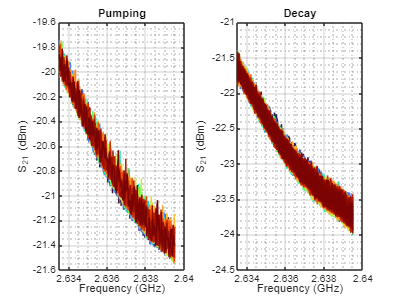

% Smoothing
zz = smoothdata(zz,'movmean', 4);
zzph = smoothdata(zzph, 'movmean', 4);

% Pumping & Decay
plot_pumping_decay(freq, zz, pumping_zz)


%% Correction Procedure
[zz_corrected, zzph_corrected] = circle_correction(zz, zzph, 40);

zzph_corrected = smoothdata(zzph_corrected, 'movmean', 2);
zz_corrected = smoothdata(zz_corrected, 'movmean', 2);

% %% Comparison Plot

cc = turbo(size(zz,2));
% plot_comparison(freq, zz,zz_corrected, zzph, zzph_corrected);

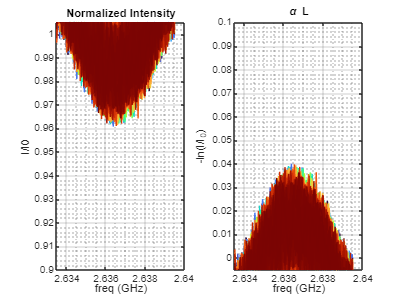

%% Intensity Plot
% [transmat, alpha_L] = intensity_analysis_visualization(freq, zz_corrected,[0.9 1.005], [-0.005 0.1]);
[transmat, alpha_L] = intensity_analysis_visualization(freq, db2mag(zz),[0.9 1.005], [-0.005 0.1]);

%% Plot Decay & Exponential Fit

tr_l = alpha_L(:, end);
[max_tr1, fr_idx] = max(tr_l);

minus_alpha_L = -alpha_L;

fr_max = freq(fr_idx);

% Tri-exponential fit

fit_func = fittype('a * exp(-1/tau1*x) + b * exp(-1/tau2*x) + c * exp(-1/tau3*x) + offset',...
    dependent="y",independent="x",...
    coefficients=["a", "tau1", "b", "tau2", "c", "tau3", "offset"]);
[f, gof] = fit(xx',minus_alpha_L(fr_idx, :)', fit_func, 'StartPoint',[10, 4000, 10, 400, 10, 40, -2], 'Robust', 'LAR');

Fitting stopped because the number of iterations or function evaluations exceeded the specified maximum.



fit_coeff = coeffvalues(f);
var_names = string(coeffnames(f))'

var_names = 1×7 string array
    "a"    "tau1"    "b"    "tau2"    "c"    "tau3"    "offset"


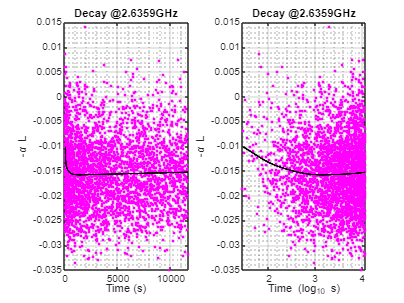


figure;
subplot(1,2,1)
plot(xx, minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (s)")
ylabel("-\alpha L")
hold on
plot(xx, f(xx), 'Color','Black', 'LineWidth',1.5)

subplot(1,2,2)
plot(log10(xx), minus_alpha_L(fr_idx, :), 'm.')
grid on; grid minor
title(strcat("Decay @", num2str(fr_max), "GHz"))
xlabel("Time (log_{10} s)")
ylabel("-\alpha L")

hold on
plot(log10(xx), f(xx), 'Color','Black', 'LineWidth',1.5)


T = table(fit_coeff(1,1), fit_coeff(1,3), fit_coeff(1,5), fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6), ...
    'VariableNames', {'a', 'b', 'c', 'tau1', 'tau2', 'tau3'})

T = 1×6 table
        a           b            c           tau1        tau2      tau3 
    _________    ________    _________    __________    ______    ______

    -0.026885    0.003045    0.0060679    4.9653e+05    263.24    40.812



T1 = [T1; fit_coeff(1,2), fit_coeff(1,4), fit_coeff(1,6)]

### B-field dependent T1

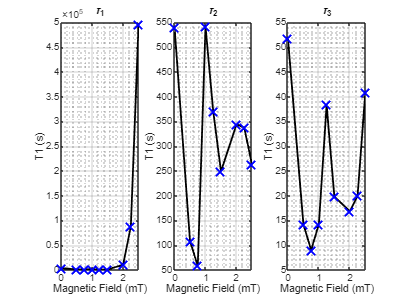

B_field = [0 0.5 0.75 1 1.25 1.5 2 2.25 2.5];
T1 = [
    3260.974437,  540.3903014,  51.77677559;
    708.8885555,  107.5407412,  14.18576292;
    663.0183462,   57.97694496,  8.98679935;
   1024.053314,  542.373899,  14.22162851;
    422.4953192,  369.9890236,  38.34374112;
    643.5409065,  248.9064433,  19.77573051;
   9971.99564,  343.7509201,  16.83425909;
  87155.9862,  337.7205654,  19.95841006;
 496532.4128,  263.235371,  40.81154177
];

figure;
subplot(1,3,1)
plot(B_field, T1(:,1)','k-', 'Marker', 'x', 'MarkerSize', 10, 'MarkerEdgeColor', 'blue', 'LineWidth', 1.5)
grid on; grid minor
title('\tau_1')
xlabel('Magnetic Field (mT)')
ylabel('T1 (s)')

subplot(1,3,2)
plot(B_field, T1(:,2)','k-', 'Marker', 'x', 'MarkerSize', 10, 'MarkerEdgeColor', 'blue', 'LineWidth', 1.5)
grid on; grid minor
title('\tau_2')
xlabel('Magnetic Field (mT)')
ylabel('T1 (s)')

subplot(1,3,3)
plot(B_field, T1(:,3)','k-', 'Marker', 'x', 'MarkerSize', 10, 'MarkerEdgeColor', 'blue', 'LineWidth', 1.5)
grid on; grid minor
title('\tau_3')
xlabel('Magnetic Field (mT)')
ylabel('T1 (s)')